Open it as live script!!!

Load data.

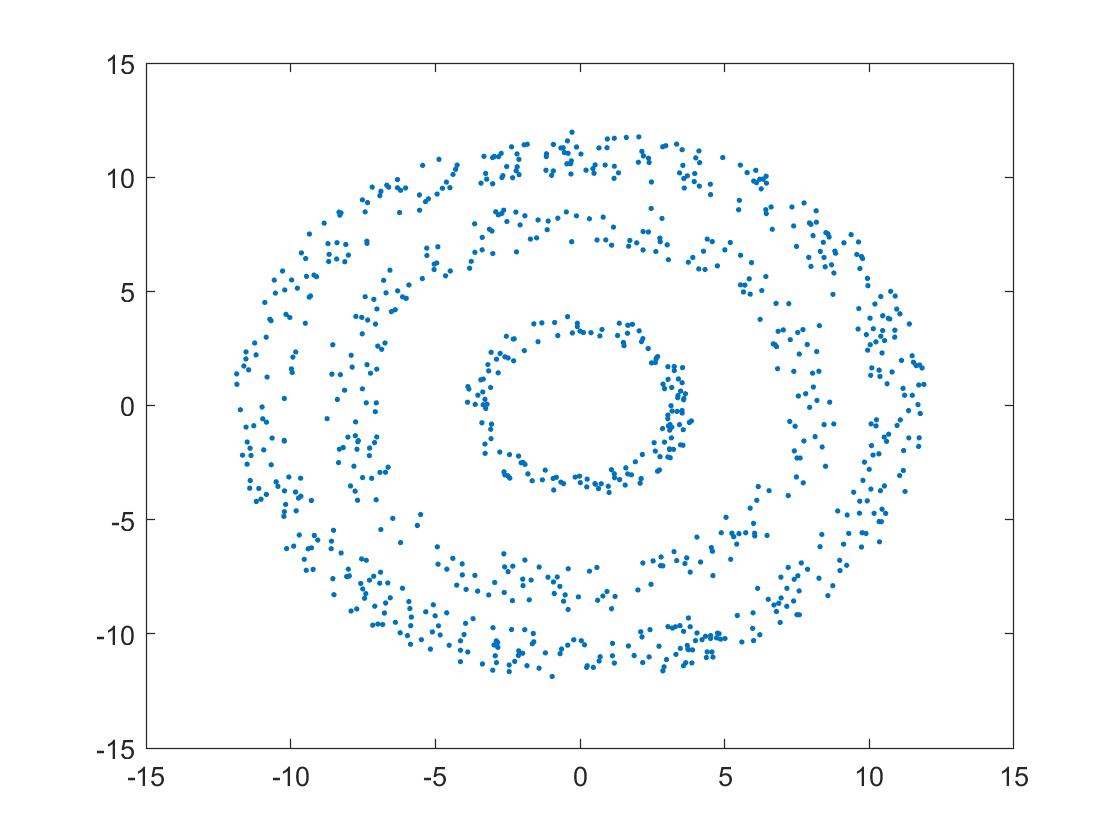

load('Data\cluster_data.mat');
% X = csvread('twomoon-2d-50s.test.csv');
X = cluster_data;
plot(X(:, 1), X(:, 2), '.');

k is the number of clusters.

k = 3;
X = (X - mean(X, 1)) ./ (max(X, [], 1) - min(X, [], 1));
y = SpectralClustering(X, k, 0.1);

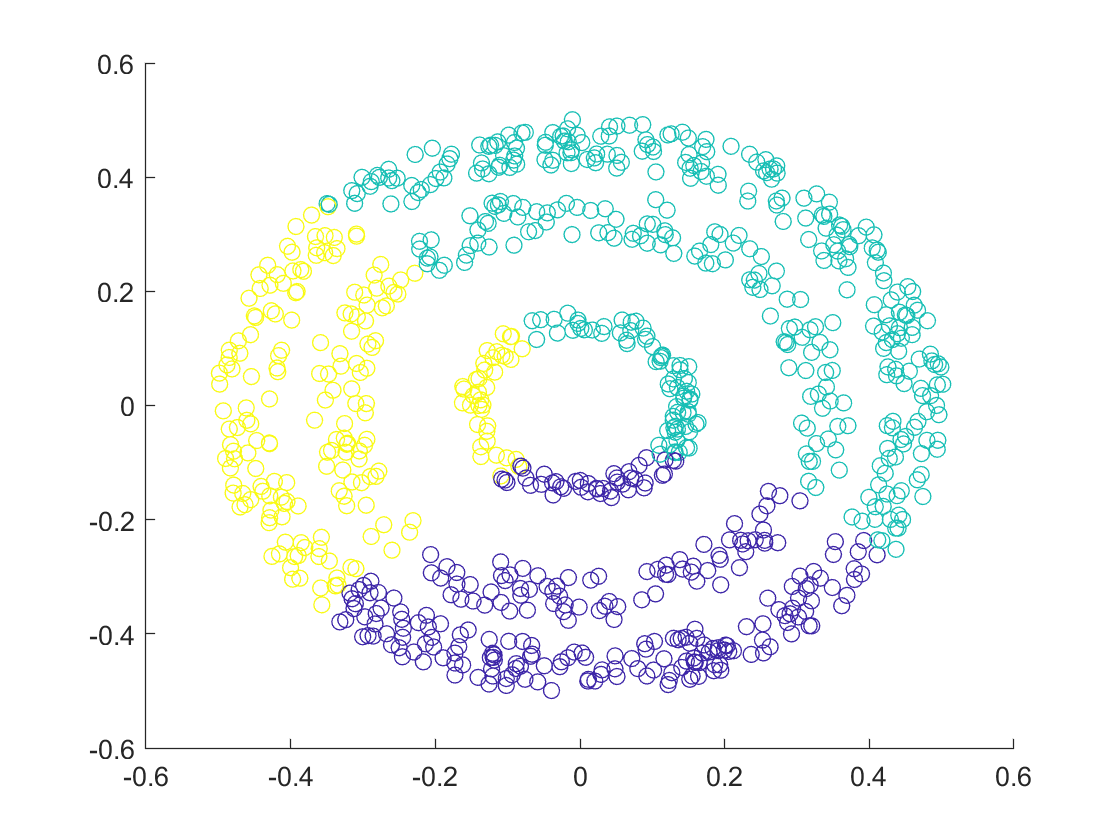

scatter(X(:, 1), X(:, 2), [], y);